# Chaotic model supported on a 4D mixed-mode SSM

clearvars
close all
clc

In this notebook we investigate a fluid - structure interaction problem. A flexible sheet, the flag, is placed in a water tunnel. The trailing edge (with respect to the flow direction) is clamped. 

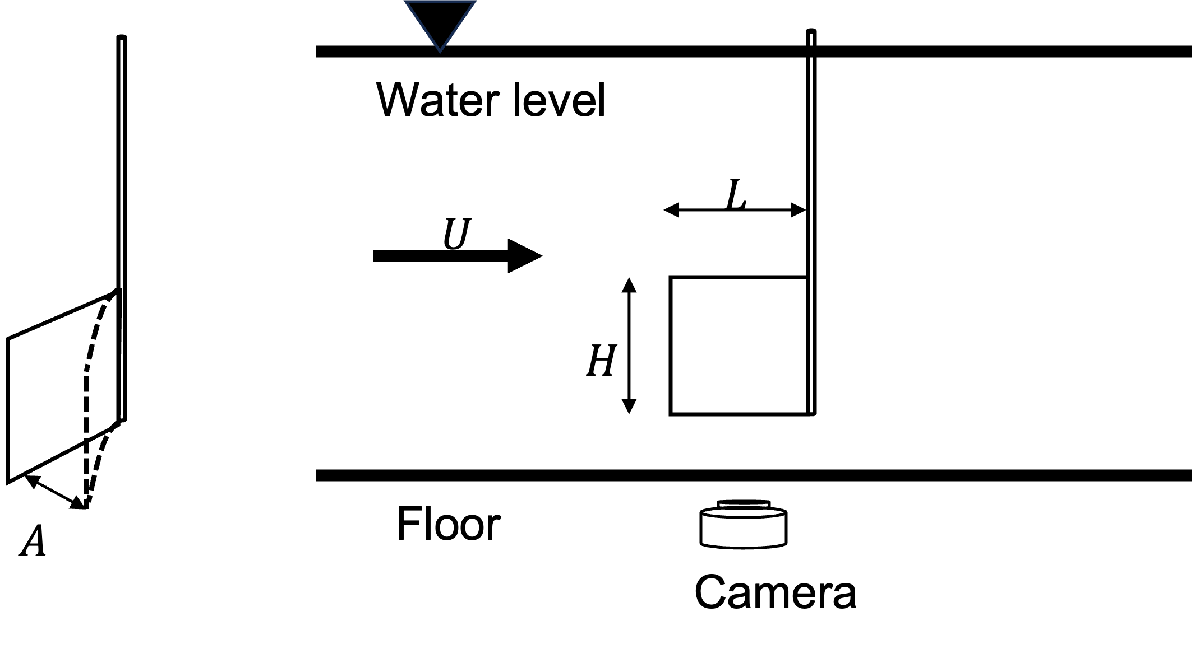

(Experiments taken in Coletti Lab: Institute of Fluid Dynamics, ETH Zurich)

The dynamics of an inverted flag exhibit different regimes as flow velocities increase in the water tunnel, leading to a decrease in the system's stiffness $K_B$. We briefly present the bifurcation diagram of an inverted flag and highlight the two states upon which our models are built: regular flapping and chaotic flapping.

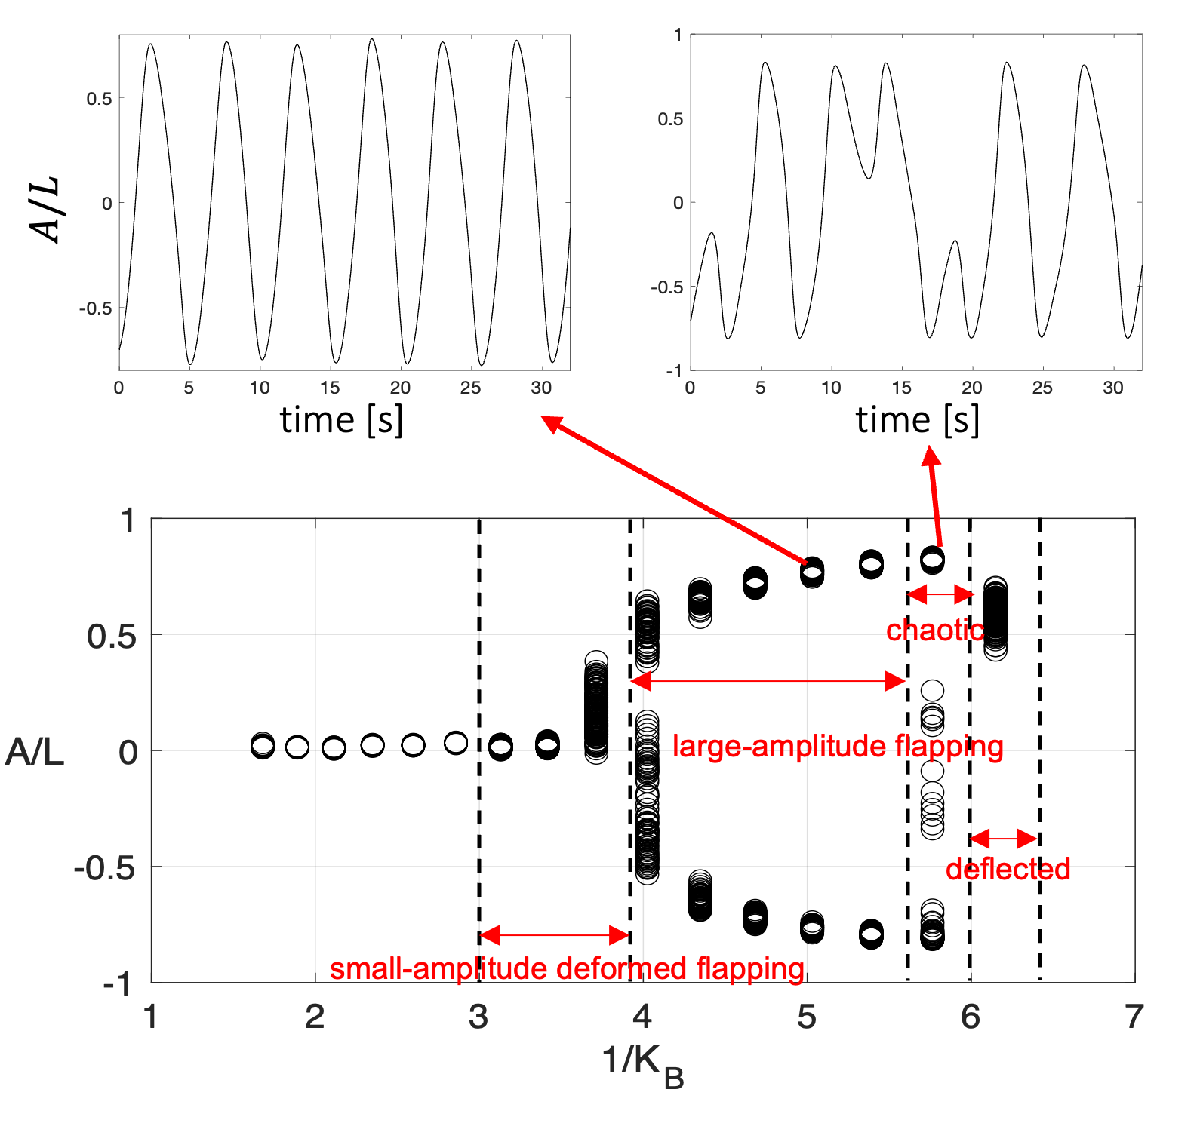

In this notebook, we reduce dynamics of the inverted flag to a 4D SSM which supports chaotic dynamics. 

## 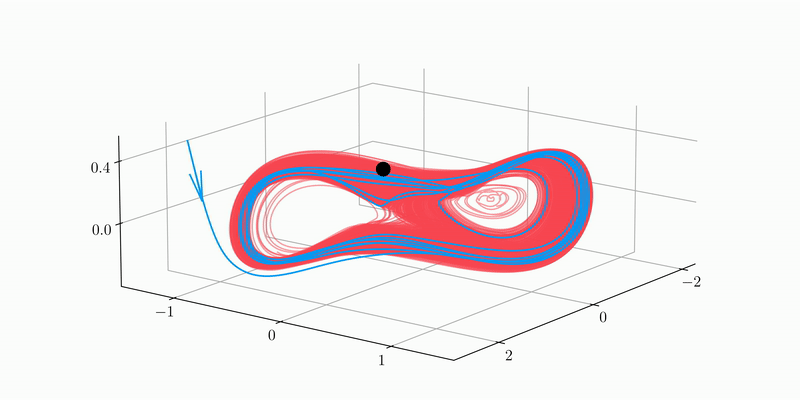

### References

[1] Z. Xu, B. Kaszás, M. Cenedese, G. Berti, F. Coletti, G. Haller, Data-driven modeling of the regular and chaotic dynamics of an inverted flag from experiments, J. Fluid Mech. (2024) 

[2] J. E. Sader, J. Cosse,  D. Kim, B. Fan, M. Gharib, Large-amplitude flapping of an inverted flag in a uniform steady flow–a vortex-induced vibration. J. Fluid Mech. 793, (2016)

[3] A. Liu, J. Axas, G. Haller, Data-driven modeling and forecasting of chaotic dynamics on inertial manifolds constructed as spectral submanifolds. Chaos 34 (3), 033140, (2024)

## Loading the chaotic time series

When we reduce the stiffness parameter, to a value of $\frac{1}{K_B }=5\ldotp 9$, the system is in the chaotic flapping regime. We have performed 10 experiments, with around 2-6 minutes of runtime each. Although the flag is still mainly exhibits large-amplitude flapping behavior, this is now aperiodic and is often characterized as chaotic. 

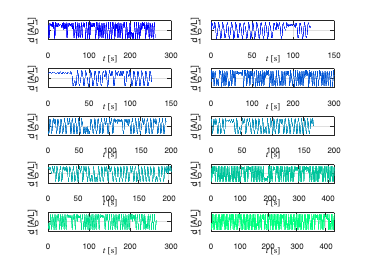


load('chaotic_trajectories.mat');
%% plot of trajectories in the experiments
nTraj = 10;
customFigure('subPlot',[nTraj/2 2]); colors = winter(nTraj);
for i = 1:nTraj
    subplot(nTraj/2,2,i); hold on; grid on; box on;
    plot(xData{i,1},xData{i,2},'Linewidth',1,'Color',colors(i,:))
    xlabel('$t \, [$s$]$','Interpreter','latex')
    ylabel('d [A/L]')
end

% selecting the training and test trajectories
indTrain = [2:10];
indTest = 1;

## Manifold fitting

The slowest mixed-mode SSM of the unstable fixed point is two-dimensional and cannot account for the chaotic behavior observed in the experiments. We therefore reduce the dynamics to the second slowest mixed-mode SSM. The dynamics of the flag close to the undeflected state resemble those of a buckling beam owing to their common divergence mechanism [2], which means that all other eigenvalues, except for those contained in the slowest mixed-mode spectral subspace, are complex. Increasing the dimensionality of the SSM therefore requires including the next slowest 2-dimensional spectral subspace.

To fit the 4-dimensional manifold, we first create delay-embedded observable vectors. The reduced coordinates are obtained via PCA. 



SSMDim = 4;
indTrain = [2:10];
indTest = 1;
yData = coordinatesEmbedding(xData, SSMDim, 'TimeStepping', 4);

The 9 embedding coordinates consist of the measured state and its 8 time-delayed measurements.


SSMOrder = 3;
IMInfo_temp = IMGeometry(yData(indTrain,:), SSMDim, 1);  % compute reduced coordinates with a linear projection
etaData = projectTrajectories(IMInfo_temp, yData);
IMInfo = IMGeometry(yData(indTrain,:), SSMDim, SSMOrder, 'reducedCoordinates', etaData(indTrain,:)); % we specify the reduced coordinates for the parametrization


% compute the (static) reconstruction error
yRec = liftTrajectories(IMInfo, etaData);
fullTrajDist = computeTrajectoryErrors(yRec, yData);
NMTE_train = mean(fullTrajDist(indTrain))

NMTE_train = 0.0015

NMTE_test = mean(fullTrajDist(indTest))

NMTE_test = 0.0018

## Reduced order model

To determine the reduced dynamics, we now choose an approximation method different from polynomials, since those were found inaccurate by [3]. Instead, we approximate the reduced dynamics using radial basis functions (RBFs). The next-step prediction for the reduced coordinate $$\mathbf{\eta}$$ is written as


$$\eta_{n+1} =F\left(\eta \;\right)=\sum_{i=1} C_i k\left(||\;\eta_n -\eta_i ||\right),$$


where $k$  is a radial kernel, which we simply take as the identity here, and $\eta_i$ are the reduced coordinates in the training set. We first determine the coefficients $C_i$ by linear regression using the training set. Then, the coefficients can be used to evaluate the reduced dynamics. 

% we first construct the eta_n and eta_n+1 for the training set: 
eta_n = [];
eta_n_plus_1 = [];

for iTraj = indTrain
    eta_n = [eta_n, etaData{iTraj,2}(:, 1:end-1);];
    eta_n_plus_1 = [eta_n_plus_1, etaData{iTraj,2}(:, 2:end);];
end

rbfInterpolator = RBF_interpolator(eta_n, eta_n_plus_1);

## Evaluation: short time prediction

We predict the time evolutaion of each trajectory in the training and test sets using the RBF-approximation for the reduced dynamics. We then lift these predictions with the parametrization to obtain the physical tip displacement. 

etaPred = {};
for iTraj = 1:10
    etaPred{iTraj, 1} = etaData{iTraj, 1};    
    predicted_ = [etaData{iTraj, 2}(:,1)];
    length = size(etaData{iTraj, 2},2);
    for i = 1 : length -1 
        predicted_ = [predicted_, rbfInterpolator.evaluate(predicted_(:,end))];
    end
    etaPred{iTraj, 2} = predicted_;
end
yDataPred = liftTrajectories(IMInfo, etaPred);

Note, that due to the chaotic behavior, prediction of individual trajectories is only valid for short times. 

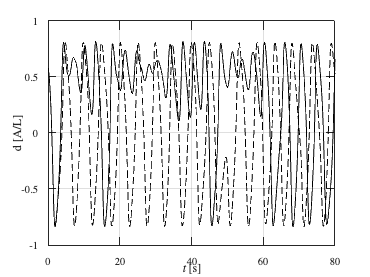

customFigure('latex', true);
hold on;
plot(yDataPred{indTest, 1}, yData{indTest, 2}(1,:),  '-', 'Color','black', 'DisplayName','Experiment')
plot(yDataPred{indTest, 1}, yDataPred{indTest, 2}(1,:), '--', 'Color','black', 'DisplayName','SSM-based prediction')
xlim([0, 80])
xlabel('$t \, [$s$]$','Interpreter','latex')
ylabel('d [A/L]')

## Evaluation: invariant measure of the chaotic attractor

We now demonstrate that our SSM-reduced model has the same dynamics, in a qualitative sense, as the experimentally observed one. If the dynamics take place on a chaotic attractor, this is the best one can hope for, since predictions of individual trajectories become meaningless. Instead we choose to characterize large ensembles of trajectories and their statistics.

We assume that the system is ergodic, and so we can exchange temporal and ensemble averages to compute the invariant measure of the attractor.

% Concatenate the model-predicted reduced coordinates
eta_n_predicted = [];
for iTraj = indTrain
    eta_n_predicted = [eta_n_predicted, etaPred{iTraj,2}(:, 1:end-1);];
end

### Projection of the invariant measure on the $\eta_1 -\eta_2 \;$ plane

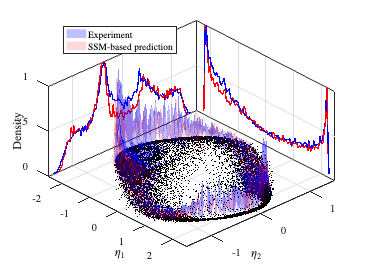

customFigure('latex', true);
hold on
grid on;
plot(eta_n(1,:), eta_n(2,:),'.', 'color', 'black', 'markersize', 2.)
[counts_model, Xedge, Yedge] = histcounts2(eta_n_predicted(1,:),eta_n_predicted(2,:), 100, 'normalization', 'percentage');
[counts_exp, Xedge, Yedge] = histcounts2(eta_n(1,:),eta_n(2,:), 100, 'normalization', 'percentage');
[X_plot, Y_plot] = meshgrid(Xedge(1,1:end-1), Yedge(1,1:end-1));
counts_exp = counts_exp / max(counts_exp, [], 'all');
counts_exp(counts_exp == 0) = nan;

counts_model = counts_model / max(counts_model, [], 'all');
counts_model(counts_model == 0) = nan;

s1 = surf(X_plot, Y_plot, counts_exp', 'FaceAlpha',0.25, 'FaceColor','blue');
s1.EdgeColor = 'none';
s2 = surf(X_plot, Y_plot, counts_model', 'FaceAlpha',0.15, 'FaceColor','red');
s2.EdgeColor = 'none';

xl = [-2.5, 2.5];
yl = [-1.5, 1.5];

xlim(xl);
ylim(yl);
[counts_1d_x_exp, edges] =  histcounts(eta_n(1,:), 100, 'Normalization', 'percentage');
counts_1d_x_exp = counts_1d_x_exp / max(counts_1d_x_exp);
plot3(edges(:, 1:end-1), yl(2) + edges(:, 1:end-1)*0, counts_1d_x_exp, '-', 'linewidth', 2, 'Color', 'blue', 'DisplayName','Experiment')
[counts_1d_x_model, edges] =  histcounts(eta_n_predicted(1,:), 100, 'Normalization', 'percentage');
counts_1d_x_model = counts_1d_x_model / max(counts_1d_x_model);
plot3(edges(:, 1:end-1), yl(2) + edges(:, 1:end-1)*0, counts_1d_x_model, '-', 'linewidth', 2, 'Color', 'red', 'DisplayName','SSM-based prediction')


[counts_1d_x_exp, edges] =  histcounts(eta_n(2,:), 100, 'Normalization', 'percentage');
counts_1d_x_exp = counts_1d_x_exp / max(counts_1d_x_exp);
plot3(xl(1) + edges(:, 1:end-1)*0, edges(:, 1:end-1), counts_1d_x_exp, '-', 'linewidth', 2, 'Color', 'blue')
[counts_1d_x_model, edges] =  histcounts(eta_n_predicted(2,:), 100, 'Normalization', 'percentage');
counts_1d_x_model = counts_1d_x_model / max(counts_1d_x_model);
plot3(xl(1) + edges(:, 1:end-1)*0, edges(:, 1:end-1), counts_1d_x_model, '-', 'linewidth', 2, 'Color', 'red')
view(47, 47);
xlabel('$\eta_1$');
ylabel('$\eta_2$');
zlabel('Density');
legend([s1, s2], {'Experiment', 'SSM-based prediction'}, 'location', 'best')

### Projection of the invariant measure on the $\eta_3 -\eta {\;}_4$ plane

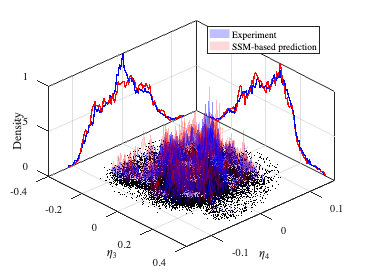

customFigure('latex', true);
hold on
grid on;
plot(eta_n(3,:), eta_n(4,:),'.', 'color', 'black', 'markersize', 2.)
[counts_model, Xedge, Yedge] = histcounts2(eta_n_predicted(3,:),eta_n_predicted(4,:), 100, 'normalization', 'percentage');
[counts_exp, Xedge, Yedge] = histcounts2(eta_n(3,:),eta_n(4,:), 100, 'normalization', 'percentage');
[X_plot, Y_plot] = meshgrid(Xedge(1,1:end-1), Yedge(1,1:end-1));
counts_exp = counts_exp / max(counts_exp, [], 'all');
counts_exp(counts_exp == 0) = nan;

counts_model = counts_model / max(counts_model, [], 'all');
counts_model(counts_model == 0) = nan;

s1 = surf(X_plot, Y_plot, counts_exp', 'FaceAlpha',0.25, 'FaceColor','blue');
s1.EdgeColor = 'none';
s2 = surf(X_plot, Y_plot, counts_model', 'FaceAlpha',0.15, 'FaceColor','red');
s2.EdgeColor = 'none';

xl = [-0.4, 0.4];
yl = [-0.15, 0.15];

xlim(xl);
ylim(yl);


% projection to x axis:
[counts_1d_x_exp, edges] =  histcounts(eta_n(3,:), 100, 'Normalization', 'percentage');
[counts_1d_x_model, edges] =  histcounts(eta_n_predicted(3,:), 100, 'Normalization', 'percentage');
normalization_factor = max([max(counts_1d_x_exp), max(counts_1d_x_model)]);
counts_1d_x_exp = counts_1d_x_exp / normalization_factor;
counts_1d_x_model = counts_1d_x_model / normalization_factor;

plot3(edges(:, 1:end-1), yl(2) + edges(:, 1:end-1)*0, counts_1d_x_exp, '-', 'linewidth', 2, 'Color', 'blue', 'DisplayName','Experiment')
plot3(edges(:, 1:end-1), yl(2) + edges(:, 1:end-1)*0, counts_1d_x_model, '-', 'linewidth', 2, 'Color', 'red', 'DisplayName','SSM-based prediction')

% projection to y axis:
[counts_1d_x_exp, edges] =  histcounts(eta_n(4,:), 100, 'Normalization', 'percentage');
[counts_1d_x_model, edges] =  histcounts(eta_n_predicted(4,:), 100, 'Normalization', 'percentage');
normalization_factor = max([max(counts_1d_x_exp), max(counts_1d_x_model)]);
counts_1d_x_exp = counts_1d_x_exp / normalization_factor;
counts_1d_x_model = counts_1d_x_model / normalization_factor;


plot3(xl(1) + edges(:, 1:end-1)*0, edges(:, 1:end-1), counts_1d_x_exp, '-', 'linewidth', 2, 'Color', 'blue')
plot3(xl(1) + edges(:, 1:end-1)*0, edges(:, 1:end-1), counts_1d_x_model, '-', 'linewidth', 2, 'Color', 'red')
view(47, 47);

xlabel('$\eta_3$');
ylabel('$\eta_4$');
zlabel('Density');
legend([s1, s2], {'Experiment', 'SSM-based prediction'}, 'location', 'best')

## Visualizing the attractor

Here we visualize the chaotic attractor predicted by our SSM-reduced model. 

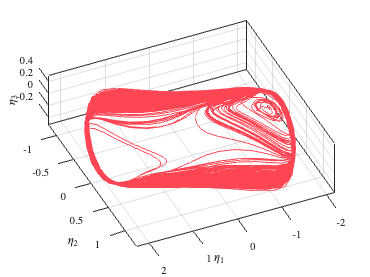

customFigure('latex', true);
hold on
grid on;
customColor = [0.9973991938671649, 0.271843841793703, 0.3312661650034482, 0.5];
for iTraj = 1:4
    plot3(etaPred{iTraj, 2}(1,:),etaPred{iTraj, 2}(2,:), etaPred{iTraj, 2}(3,:), '-', 'linewidth', 1, 'Color',customColor)

end
xlabel('$\eta_1$');
ylabel('$\eta_2$');
zlabel('$\eta_3$');
view(156, 70);

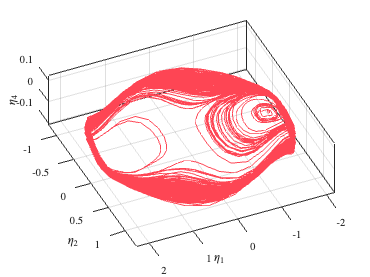


customFigure('latex', true);
hold on
grid on;
for iTraj = 1:4
    plot3(etaPred{iTraj, 2}(1,:),etaPred{iTraj, 2}(2,:), etaPred{iTraj, 2}(4,:), '-', 'linewidth', 1, 'Color',customColor)

end
xlabel('$\eta_1$');
ylabel('$\eta_2$');
zlabel('$\eta_4$');
view(156, 70);